clear;clc
load Cz.mat
load STD_Cz.mat
load MQC.mat
load std_zeroorder.mat
load std_otherorder_norm.mat

xi_y=[-0.2,-0.15,-0.1,-0.05,-0.025,0,0.025,0.05,0.1,-0.175:0.05:-0.075];
xi_x=0.1;
xi_z=-xi_x-xi_y;
W_z=-6*xi_x*xi_y;

num_loop=18;
tau=5*1e-6; %in us
quench_time=(0:num_loop-1)*24*tau*1e3; %in ms

J_bar=1.4595; %in kHz


## Display the zeroth and second order MQC

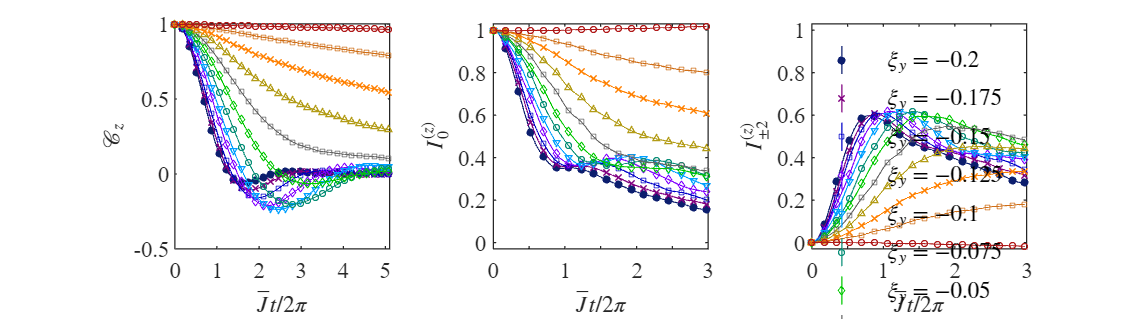

figure()
marker={'.','x','s','d','v','o','d','s','^','x','s','o','^'};
markersize=[8,3,2,2,2,2,2,2,2,3,2,2,2]*1.2;
color={'#0C1E6E','#800080','#0000C8','#8000FF','#00A0FF','#0A8F78','#00C800','#666666','#B39C17','#FF8000','#CF6E17','#B01919','#FF0000'};

figure()

subplot(1,3,1)
xi_y_2=-0.2:0.025:0.1;

endpoint=30;
quench_time2=(0:40)*24*tau*1e3; %in ms
x2=quench_time2(1:endpoint)*J_bar;

jj=1;

t_dip_AutoCorre=zeros(1,length(xi_z));
for j=[1:11,13]
    y2=S(j,1:endpoint);
    
    xx=linspace(x2(1),x2(end),100000);
    yy=spline(x2,y2,xx);
    [~,index]=min(yy);
    t_dip_AutoCorre(jj)=xx(index);

    error_bar=1.96*STD_S(j,1:endpoint);
    errorbar(x2,y2,error_bar,marker{jj},'MarkerSize',markersize(jj),'capsize',0,'color',color{jj});
    hold on
    plot(xx,yy,'color',color{jj})
    xlabel('$\bar{J}t/2\pi$','Interpreter','latex')
    ylabel('$\mathcal{C}_z$','Interpreter','latex')
    xticks([0:5])
    xlim([0 5.1])
    jj=jj+1;
end

[xi_y_sorted,index_xi_y]=sort(xi_y,'ascend');

subplot(1,3,2)
mqc_zero=zeros(length(xi_z),num_loop);
t_dip_0MQC=zeros(1,length(xi_z));
for j=1:length(xi_z)
    mqc=MQC{index_xi_y(j)};
    mqc_zero(j,:)=mqc(:,1);
    error_bar=1.96*std_zeroorder_norm(:,j);
    x=quench_time*J_bar;

    b=errorbar(x,mqc(:,1),error_bar,marker{j},'MarkerSize',markersize(j),'capsize',0,'color',color{j});
    hold on
    xlabel('$\bar{J}t/2\pi$','Interpreter','latex')
    ylabel('$I_{0}^{(z)}$','Interpreter','latex')

    ylim([-0.03  1.03])
    yticks([0:0.2:1])

    xlim([0 3])
    xticks([0:0.5:5])
    xticklabels({'0','','1','','2','','3'})

    xx=linspace(x(1),x(end),100000);
    yy=spline(x,mqc(:,1),xx);
    [~,index]=findpeaks(-yy);
    if length(index)~=0
    t_dip_0MQC(j)=xx(index(1));
    end
    plot(xx,yy,'color',color{j})
end
% set(gca,'Yscale','log')

t_peak_2MQC=zeros(1,length(xi_z));
mqc_second=zeros(length(xi_z),num_loop);

subplot(1,3,3)
for j=1:length(xi_z)
    mqc=MQC{index_xi_y(j)};
    mqc_second(j,:)=mqc(:,3);
    error_bar=2*1.96*std_otherorder_norm(:,j);
    x=quench_time*J_bar;

    b=errorbar(x,2*mqc(:,3),error_bar,marker{j},'MarkerSize',markersize(j),'capsize',0,'color',color{j});

    hold on
    xlabel('$\bar{J}t/2\pi$','Interpreter','latex')
    ylabel('$I_{\pm2}^{(z)}$','Interpreter','latex')


    ylim([-0.03 1.03])
    yticks([0:0.2:1])

    xlim([0 3])
    xticks([0:0.5:5])
    xticklabels({'0','','1','','2','','3'})

    xx=linspace(x(1),x(end),100000);
    yy=spline(x,2*mqc(:,3),xx);
    [~,index]=max(yy);
    t_peak_2MQC(j)=xx(index);
    plot(xx,yy,'color',color{j})
end
legend('$\xi_y=-0.2$','','$\xi_y=-0.175$','','$\xi_y=-0.15$','','$\xi_y=-0.125$','','$\xi_y=-0.1$'...
        ,'','$\xi_y=-0.075$','','$\xi_y=-0.05$','','$\xi_y=-0.025$','','$\xi_y=0$','','$\xi_y=0.25$','','$\xi_y=0.5$',...
        '','$\xi_y=0.1$','interpreter','latex','box','off')


fontsize(gcf,9,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,16,4.5]);
set(gca,'XTickLabelRotation',0)

## Compare the period of the MQC and autocorrelation

xi_y_auto_corre=-0.2:0.025:0.1;

figure()
subplot(1,3,1)
plot(xi_y_auto_corre(1:6),t_dip_AutoCorre(1:6),'-o','MarkerFaceColor','#4a72aa','markersize',4)
hold on
plot(xi_y_sorted(1:6),t_dip_0MQC(1:6),'-^','markersize',4)
plot(xi_y_sorted(1:6),t_peak_2MQC(1:6),'-s','MarkerFaceColor','#e2754f','color','#e2754f','markersize',4)

xlabel('$\xi_y$','interpreter','latex')
ylabel('$\bar{J}t_c/2\pi$','interpreter','latex')
% legend('$t_{\mathrm{dip}}^{(\mathcal{C})}$ of $\mathcal{C}_z(t)$','$t_{\mathrm{dip}}^{(I)}$ of $I_0^{(z)}(t)$ ','$t_{\mathrm{peak}}^{(I)}$ of $I_{\pm2}^{(z)}(t)$ ','interpreter','latex','box','off')

ylim([0 4])
xlim([-0.2 -0.05])
xticks([-0.2:0.025:0])
xticklabels({'-0.2','','-0.15','','-0.1','','-0.05','','0'})
set(gca,'XTickLabelRotation',0)

subplot(1,3,2)
x=t_dip_AutoCorre(1:6);
y=t_dip_0MQC(1:6);

plot(x,y,'o','Color','#4a72aa','markersize',4)
ylabel('$\bar{J}t_{\mathrm{dip}}^{(I)}/2\pi$','interpreter','latex')
xlabel('$\bar{J}t_{\mathrm{dip}}^{(\mathcal{C})}/2\pi$','interpreter','latex')

% fun = @(aa,x) aa(2)+aa(1)*x;
% a0 = [0.5,0];
fun = @(aa,x) aa*x;
a0 = [0.5];

[aa,resnorm,residual,~,~,~,jacobian] =lsqcurvefit(fun,a0,x,y);


找到局部最小值。

优化已完成，因为梯度大小小于
最优性容差的值。

<停止条件详细信息>


aa

aa = 0.5606

CI =nlparci(aa,residual,'Jacobian',jacobian);
CI_aa1=1/2*(CI(1,2)-CI(1,1))

CI_aa1 = 0.0355


xx=linspace(x(1),x(end),100);
yy=fun(aa,xx);

hold on
plot(xx,yy)
% legend('',['$y=',num2str(roundn(aa(1),-3)),'x',num2str(roundn(aa(2),-3)),'$'],'interpreter','latex','box','off')
% legend('',['$y=ax, a=',num2str(roundn(aa(1),-2)),'\pm',num2str(roundn(CI_aa1,-2)),'$'],'interpreter','latex','box','off')
legend('',['$y=0.56(4)x$'],'interpreter','latex','box','off')
ylim([0.6 1.7])


subplot(1,3,3)
x=t_dip_AutoCorre(1:6);
y=t_peak_2MQC(1:6);

plot(x,y,'s','Color','#4a72aa','markersize',4)
ylabel('$\bar{J}t_{\mathrm{peak}}^{(I)}/2\pi$','interpreter','latex')
xlabel('$\bar{J}t_{\mathrm{dip}}^{(\mathcal{C})}/2\pi$','interpreter','latex')

% fun = @(aa,x) aa(2)+aa(1)*x;
% a0 = [0.5,0];
fun = @(aa,x) aa*x;
a0 = [0.5];

[aa,resnorm,residual,~,~,~,jacobian] =lsqcurvefit(fun,a0,x,y);


找到局部最小值。

优化已完成，因为梯度大小小于
最优性容差的值。

<停止条件详细信息>


aa

aa = 0.5013

CI =nlparci(aa,residual,'Jacobian',jacobian);
CI_aa1=1/2*(CI(1,2)-CI(1,1))

CI_aa1 = 0.0107

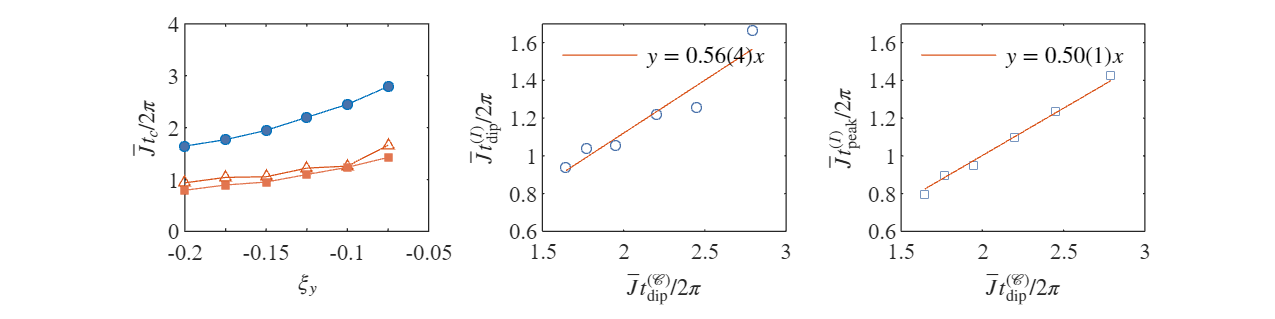


xx=linspace(x(1),x(end),100);
yy=fun(aa,xx);

hold on
plot(xx,yy)
% legend('',['$y=',num2str(roundn(aa(1),-3)),'x',num2str(roundn(aa(2),-3)),'$'],'interpreter','latex','box','off')
% legend('',['$y=ax, a=',num2str(roundn(aa(1),-2)),'\pm',num2str(roundn(CI_aa1,-2)),'$'],'interpreter','latex','box','off')
legend('',['$y=0.50(1)x$'],'interpreter','latex','box','off')
ylim([0.6 1.7])


fontsize(gcf,9,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,18,4.5]);


filename = 'Figure_S10.xlsx';
writematrix(roundn(x',-5),filename,'Sheet','Figure 4a','Range','A4')
writematrix(roundn(S1(1:31)',-5),filename,'Sheet','Figure 4a','Range','B4')
writematrix(roundn(mqc1(:,1:2:11),-5),filename,'Sheet','Figure 4a','Range','C4')
writematrix(roundn(1.96*STD_S1(1:31)',-5),filename,'Sheet','Figure 4a','Range','J4')
writematrix(roundn(1.96*std_zeroorder1,-5),filename,'Sheet','Figure 4a','Range','K4')
writematrix(roundn(1.96*std_otherorder1,-5),filename,'Sheet','Figure 4a','Range','L4')


writematrix(roundn(x',-5),filename,'Sheet','Figure 4b','Range','A4')
writematrix(roundn(S2(1:31)',-5),filename,'Sheet','Figure 4b','Range','B4')
writematrix(roundn(mqc2(:,1:2:11),-5),filename,'Sheet','Figure 4b','Range','C4')
writematrix(roundn(1.96*STD_S2(1:31)',-5),filename,'Sheet','Figure 4b','Range','J4')
writematrix(roundn(1.96*std_zeroorder2,-5),filename,'Sheet','Figure 4b','Range','K4')
writematrix(roundn(1.96*std_otherorder2,-5),filename,'Sheet','Figure 4b','Range','L4')